data = load('resultadosCSV_debug.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*2.5e6)

T_buscado =      2.000000000000000e-07


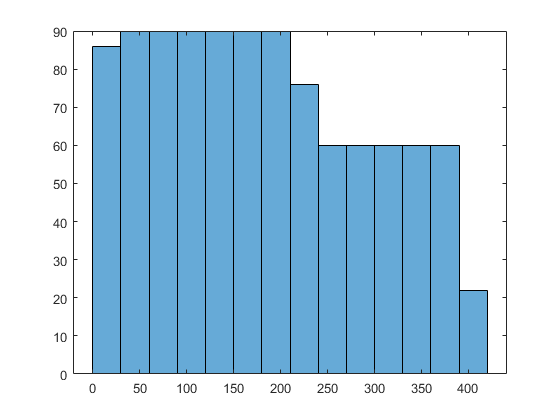

t_fino = (start)*tau_start - (stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(coarse)

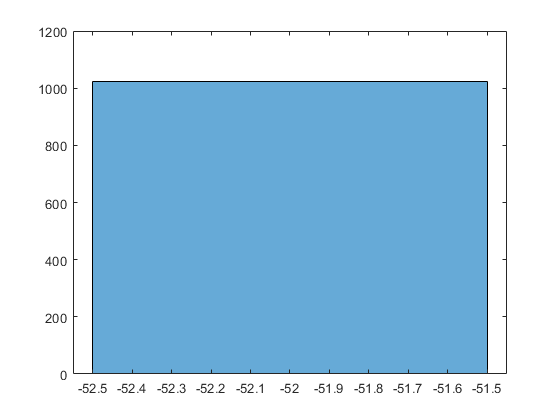

histogram(start-stop)


histogram(coarse)

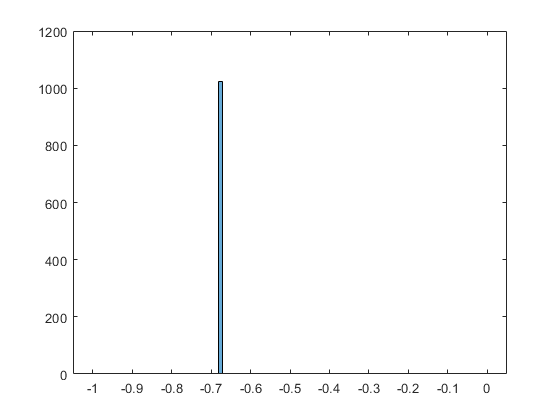

histogram(t_fino*1e9, 100)

clear;
data = load('resultadosCSV_debug_2.txt');

stop    = data(:, 1);
start   = data(:, 2);
coarse  = data(:, 3);

tau_stop    = 15.72e-12;
n_min_stop  = 35;
n_max_stop  = 353;
tau_start   = 16.23e-12;
n_min_start = 27

n_min_start =     27


n_max_start = 335

n_max_start =    335


T           = 5e-9;

T_buscado = 1/(2*2.5e6)

T_buscado =      2.000000000000000e-07


st = start-stop;
indices_st = find(st>0);
indices_st_neg = find(st<0);
st(indices_st_neg) = st(indices_st_neg) + (n_max_start-n_min_start);
st_positivo = st(indices_st);
std(st_positivo)

ans =    7.332345997736593


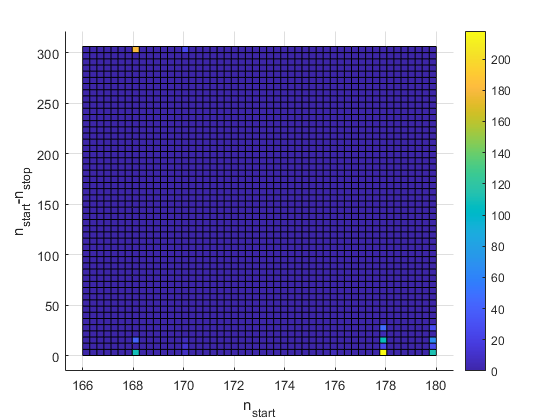

hist3([start, st], 'CdataMode','auto', 'Nbins',[50 50])
view(2); colorbar; ylabel('n_{start}-n_{stop}'); xlabel('n_{start}')
exportgraphics(gcf,'start-stop_debug.eps');

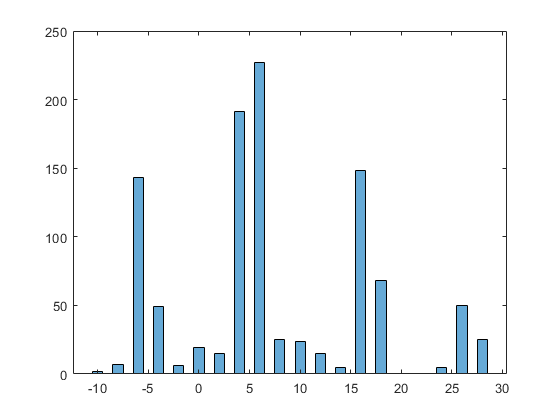

t_fino = (start-n_min_start)*tau_start - (stop-n_min_stop)*tau_stop;
t = (coarse*T) + t_fino;

histogram(start-stop)

format long
t_fino

t_fino = 	1.0e+-9 *

   0.324450000000000
   0.167250000000000
   0.481650000000000
   0.135810000000000
   0.324450000000000
   0.167250000000000
   0.261570000000000
   0.167250000000000
   0.324450000000000
   0.167250000000000



x = 1:1:1024

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


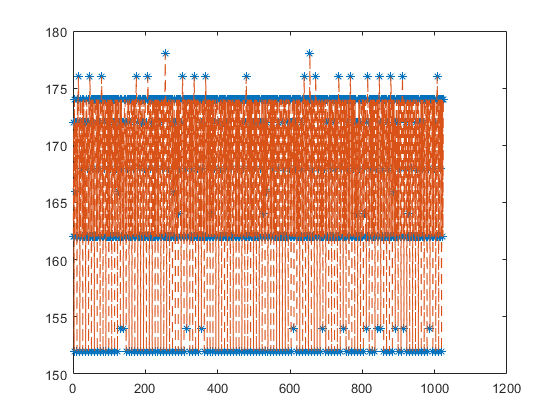

plot(x, stop, '*')
hold on;
plot(x, stop, '--')
hold off;

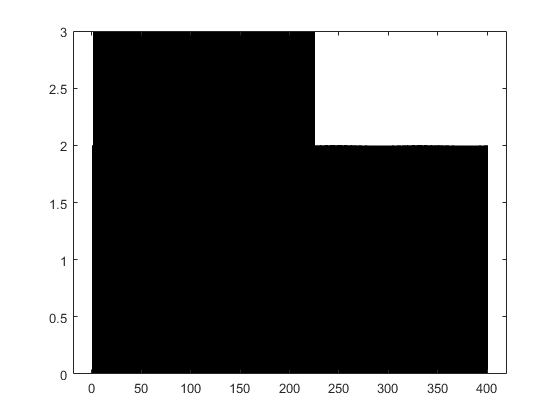

histogram(coarse, 1025)

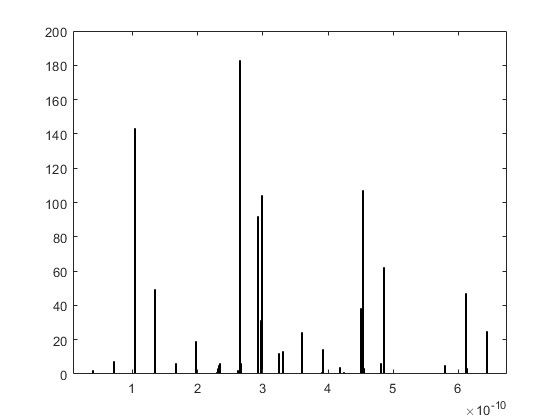

histogram(t_fino, 400)

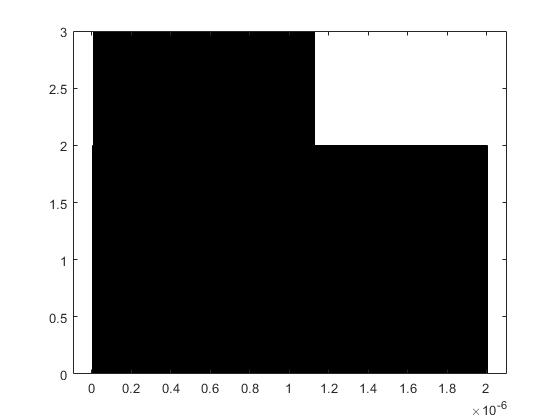

histogram(t, 400)


mean(t_fino)

ans =      3.149796093749984e-10
